# Hand in 1:

Pick an appropriate sampling frequency. Needs to be at least 6000 Hz, Pick 44100 Hz as this is industry standard. As the samples are 2 Hz apart, the signal length must hold 1/2*fs samples, which result in 0,5s worth of signal.

Fs = 44100

Fs = 44100

sample_distance = 2

sample_distance = 2

T0 = 1/sample_distance

T0 = 0.5000

target_f = 1000

target_f = 1000

Read file:

[y, fs] = audioread('HA1_IH.wav');
fs

fs = 44100

y = y(1:T0*fs);
y = y*1/max(y);

Creates the time vector and the desired signal:

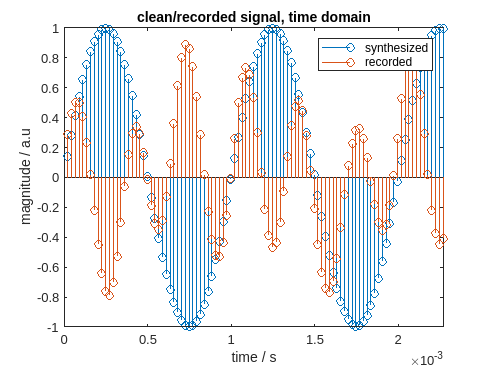

t = 1/Fs:1/Fs:T0;
f_clean = sin(2*pi*target_f*t);
figure("Name", "Plot of clean signal")
stem(t, f_clean)
hold on
stem(t, y)
xlim([0 target_f/(10*Fs)])
%fontsize(30, "pixels") %% For export only
title("clean/recorded signal, time domain")
legend({'synthesized', 'recorded'})
xlabel('time / s')
ylabel('magnitude / a.u')

Frequency analysis:

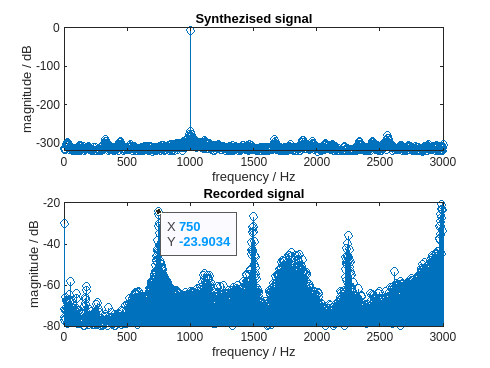

% FFT of both signals, as well as convesion to dB
[F_clean, F_vec] = make_spectrum(f_clean, Fs);
F_clean_dB = 20*log10(abs(F_clean));

[F_rec, F_rec_vec] = make_spectrum(y, Fs);
F_rec_dB = 20*log10(abs(F_rec));

% Plotting
figure("Name", "Plot of clean signal, fourier")
subplot(2,1,1)
h = stem(F_vec, F_clean_dB, 'Basevalue',-320) ;
title("Synthezised signal")
xlabel('frequency / Hz')
ylabel('magnitude / dB')
xlim([0 3000])
ylim([-320 0])

subplot(2,1,2)
h2 = stem(F_rec_vec, F_rec_dB, 'Basevalue',-320);
title("Recorded signal")
xlabel('frequency / Hz')
ylabel('magnitude / dB')
ax = gca;
%fontsize(30, "pixels") %% For export only
chart = ax.Children(1);
datatip(chart,750,-23.9);
xlim([0 3000])
ylim([-80 -20])

## Functions

function [Y, freq] = make_spectrum(signal, fs)  
    % computes spectrum (note: it will be complex-valued).

    % Makes all signal vectors contain even amounts of values.
    if (mod(length(signal),2) == 1) 
        signal = [signal 0];
    end

    % FFT is found and scaled to physically plausible values
    Y = fft(signal);
    Y = Y/(length(Y));

    % Frequency vector is generated from -fs/2 to fs/2 - 1/delta_f
    % incrementing by delta_f (1/time duration of signal).
    % The Y vector is rotated such that the values match this vector.
    T0 = length(Y)/fs;
    delta_f = 1/T0;
    freq1 = 0:delta_f:fs/2-delta_f;
    Y_1 = Y(1:length(freq1));
 
    freq2 =  -fs/2:delta_f:-delta_f;
    Y_2 = Y(length(freq1)+1:end);
    Y = [Y_2 Y_1];
    freq = [freq2 freq1];

     % convert into column vector:
    Y = Y(:);
    freq = freq(:);
    % eof
end
